B = [-27;42.45;-17.62;-0.02;-0.9375;1.7046] %La parte derecha matriz

B =   -27.0000
   42.4500
  -17.6200
   -0.0200
   -0.9375
    1.7046


%Todas las ecuaciones del spline cubico
A = [71,-48,0,0,0,0;1,6,2,0,0,0;0,2,10,3,0,0;0,0,3,14,4,0;0,0,0,4,16,4;0,0,0,0,-33/4,165/4]

A =    71.0000  -48.0000         0         0         0         0
    1.0000    6.0000    2.0000         0         0         0
         0    2.0000   10.0000    3.0000         0         0
         0         0    3.0000   14.0000    4.0000         0
         0         0         0    4.0000   16.0000    4.0000
         0         0         0         0   -8.2500   41.2500


A\B %Este es el vector que contiene todo los Cj.

ans =     4.6662
    7.4647
   -3.5021
    0.8238
   -0.2618
   -0.0110


**SPLINE CUBICO NATURAL**


% Con la nube de puntos calcule el spline cubico dado.
X = [-3 -2 1 4]

X =     -8    -1     0     2     5     9    13    20


Y =[2 0 3 1]

Y =     7.5000    6.8000   -2.3000    7.8000    5.3000    2.0100   -2.5600   -6.5800


S=csnatural(X,Y)

S =    -0.1063         0    5.1071    7.5000
    3.6459   -2.2316  -10.5142    6.8000
   -2.0805    8.7060   -4.0399   -2.3000
    0.5200   -3.7771    5.8178    7.8000
   -0.1019    0.9030   -2.8044    5.3000
    0.0379   -0.3197   -0.4709    2.0100
   -0.0065    0.1356   -1.2071   -2.5600


Note que la matriz S es la matriz de los coeficientes NATURALES de un Spline cubico. Esta rutina es para splines cubicos naturales en los cuales, entrega los coeficientes en orden descendiente. Cubico, Cuadratico, lineal y constante. VERIFIQUE. 

OJO: Este codigo solo entrga los coeficinetes a,b,c,d SIN MULTIPLICAR todos los factores. 

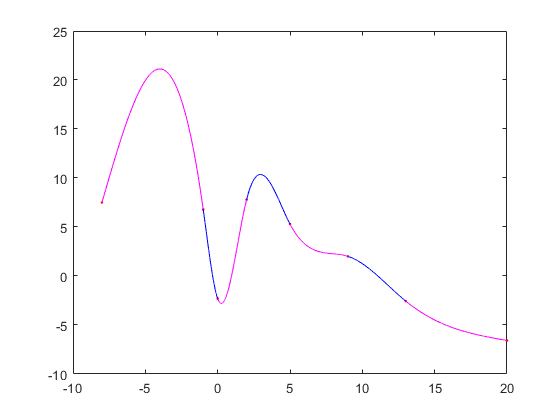

GraficaCercha(X,Y,S)%Grafica del Spline cubico

S(6,:) %De la matriz s, coja el valor de la sexta fila, todas sus columnas. Con

ans =     0.0379   -0.3197   -0.4709    2.0100


% esta instruccion estoy cogiendo S5(x). Asi con esto, vamos a realizar una
% evaluacion del spline.

Suponga que le piden evaluar en S el 11.8 ¿Como es S(11.8)?

Se mira a que intervalo pertenece, luego de ahi se selecciona al Sn y alli se evalua de la siguiente manera. PERO OJO AL SGT ERROR

malo = polyval(S(6,:),11.8)

malo = 14.2785

hold on 
plot(11.8,malo,"*r")

Claramente este punto rojo no es una buena aproximacion, de hecho, esta malo pues S hay que trasladarlo en terminos del x-xj.

Bueno = polyval(S(6,:),11.8-9) %El nueve es la x del S5. Mirar el x de S

Bueno = -0.9818

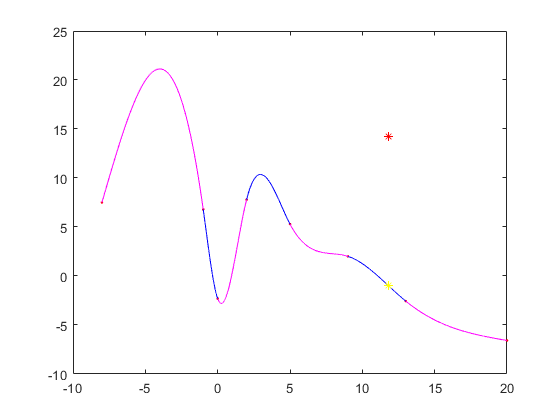

% Correspondiente a los terminos de S5 matriz S5(X)
hold on
plot(11.8, Bueno, "*y") %Este punto amarillo si está en la curva por tanto

% Si es una buena aproximacion. 

**SPLINE CUBICO SUJETO (Primera derivada)**

X = [1 2 3 4 5]

X =      1     2     3     4     5


Y = [3 -1 1 5 4]

Y =      3    -1     1     5     4


format short
S = csfit (X, Y, -1, 1) % Primero se coloca la derivada en x0 y luego xn (primeras

S =     4.5179   -7.5179   -1.0000    3.0000
   -1.5536    6.0357   -2.4821   -1.0000
   -2.3036    1.3750    4.9286    1.0000
    3.7679   -5.5357    0.7679    5.0000


% derivadas) Misma joda, de S0 a Sn.
polyval(S(1,:),1.5-1)

ans = 1.1853

**SPLINE CONOCIDO (CONOZCO 2da DERIVADAS EXTREMOS)**

X = [-3 -2 1 4]

X =     -3    -2     1     4


Y =[2 0 3 1]

Y =      2     0     3     1


format short
S=csconocido(X,Y,-1,2) %Segunda derivada x0 y segunda en Xn.

S =     0.6954   -0.5000   -2.1954    2.0000
   -0.2944    1.5862   -1.1092         0
    0.2292   -1.0632    0.4598    3.0000


polyval(S(3,:),4-2) %Deberia ser 2-4

ans = 1.5006

**SPLINE TERMINACION PARABOLICA**

S=csconstante(X,Y)

S =          0   -1.5471   10.7295    7.5000
    3.3766   -1.5471  -10.9295    6.8000
   -2.0554    8.5828   -3.8938   -2.3000
    0.5160   -3.7498    5.7721    7.8000
   -0.1002    0.8941   -2.7949    5.3000
    0.0342   -0.3089   -0.4540    2.0100
         0    0.1014   -1.2840   -2.5600


**SPLINE EXTRAPOLADO**

X = [-3 -2 1 4]

X =     -3    -2     1     4


Y = [2 0 3 1]

Y =      2     0     3     1


S=csextrapolado(X,Y)

S =    -0.1468    1.4841   -3.3373    2.0000
   -0.1468    1.0437   -0.8095         0
   -0.1468   -0.2778    1.4881    3.0000


polyval(S(2,:),0+2)

ans = 1.3810

X = [-1 0 2 3 5]

X =     -1     0     2     3     5


Y =[2 4 1 2 5]

Y =      2     4     1     2     5


format short
S=csconocido(X,Y,3,-1) %Segunda derivada x0 y segunda en Xn.

S =    -1.4050    1.5000    1.9050    2.0000
    0.8100   -2.7151    0.6900    4.0000
   -0.6953    2.1452   -0.4498    1.0000
   -0.0932    0.0591    1.7545    2.0000


polyval(S(4,:),3.5-3) %Deberia ser 2-4

ans = 2.8804

**FRONTERA COMBINADA (EXTREMOS DERIVADA DIFERENTE)**

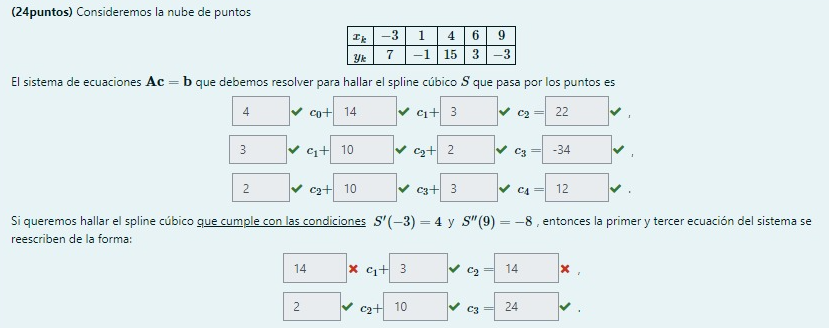

X = [-3 1 4 6 9];
Y = [7 -1 15 3 -3];
[Ac_base, B] = sistemabase(X,Y) % Sistema base

[Ac_sujeto, B] = sistemasujeto(X,Y,4,-8) %PRIMERAS DERIVADAS
%Para el problema, me fijo en la primera ecuaciones de 12c1+3c2+9=22

[Ac_curvatura, B] = sistemacurvatura(X,Y,4,-8) %2das DERIVADAS
% Para el problema nos interesa la ultima ecuaciones 2c2+10c3-12=12

Finalmente los dos sistemas que nos pide el ejercicio son:

1) 12c1+3c2=13

2) 2c2´10c3=24